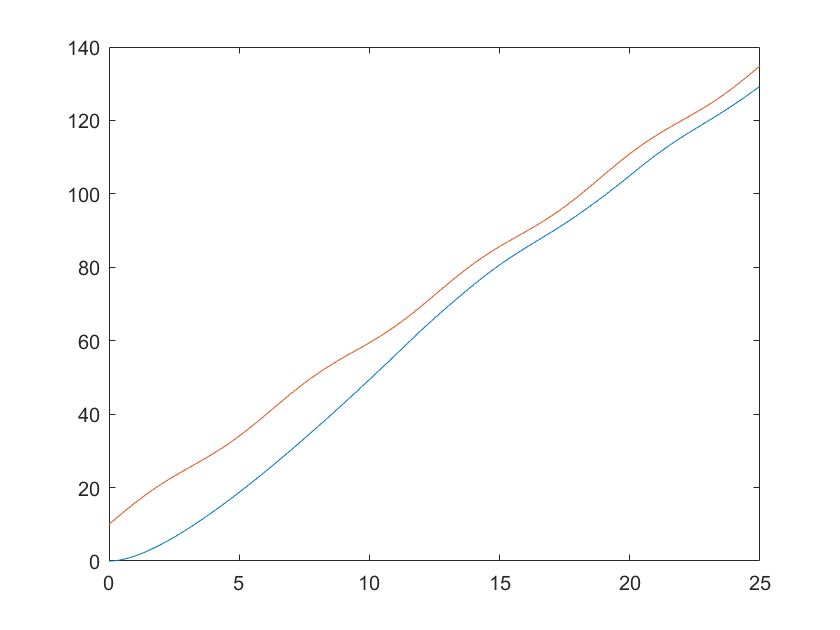

clear all
v0 = 1;
vd = 10;
Fr = 0.0;
Th = 1;

h = 0.01;
t = 0:h:25;

x0 = [0;0;0];
X = [x0, zeros(length(x0), length(t) - 1)];
F = zeros(length(t), 1);

leadCar_pos = 10 + 5*t + sin(t);
leadCar_v = 5 + cos(t);

for i = 2:length(t)

    v0 = leadCar_v(i);
    
    V = @(x) (x(2,:) - vd)^2;
    LfV = @(x) -2*(x(2) - vd)*Fr*x(2);
    LgV = @(x) 2*(x(2) - vd);

    B = @(x) x(3,:) - Th*x(2,:);
    LfB = @(x) Fr*Th*x(2) + v0 - x(2);
    LgB = @(x) -Th;

    z = leadCar_pos(i - 1) - X(1, i - 1);
    p = X(1, i - 1);
    v = X(2, i - 1);
    x = [p; v; z];
    F(i) = ctrlCbfClfQp(V, LfV, LgV, B, LfB, LgB, x, 0);
    X(2,i) = X(2,i - 1) + F(i)*h;
    X(1,i) = X(1,i - 1) + X(2,i-1)*h;
    X(3, i) = leadCar_pos(i) - X(1, i);
end



plot(t, X(1,:))
hold on
plot(t, leadCar_pos)
hold off

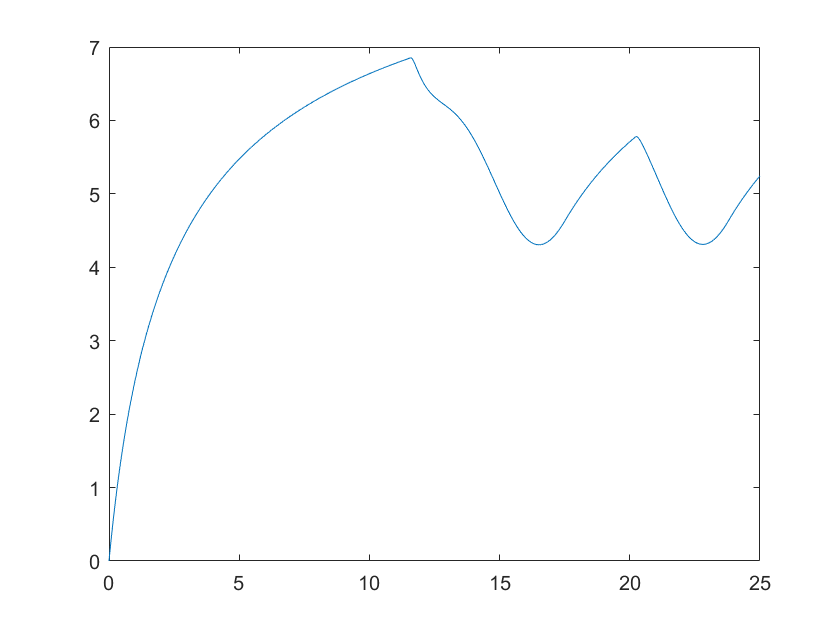


plot(t, X(2,:))

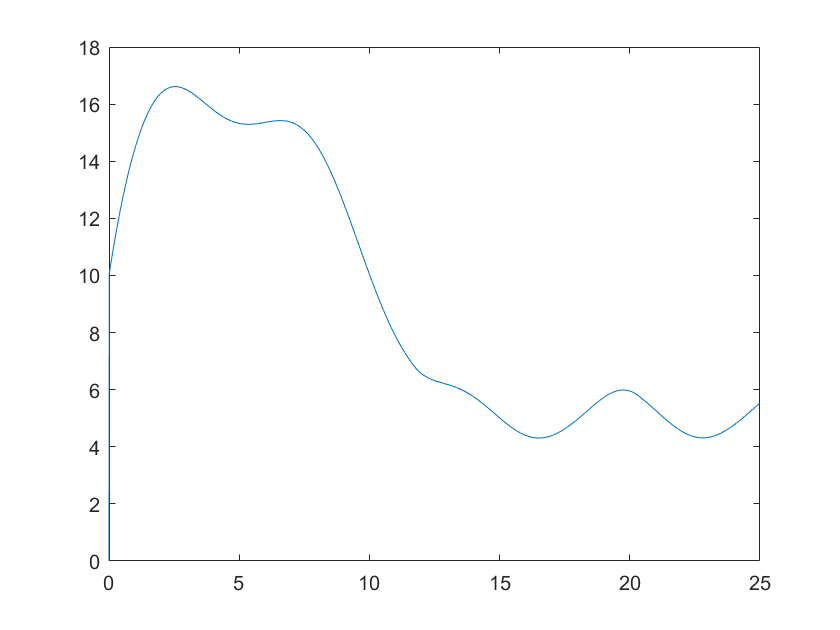

plot(t, X(3,:))

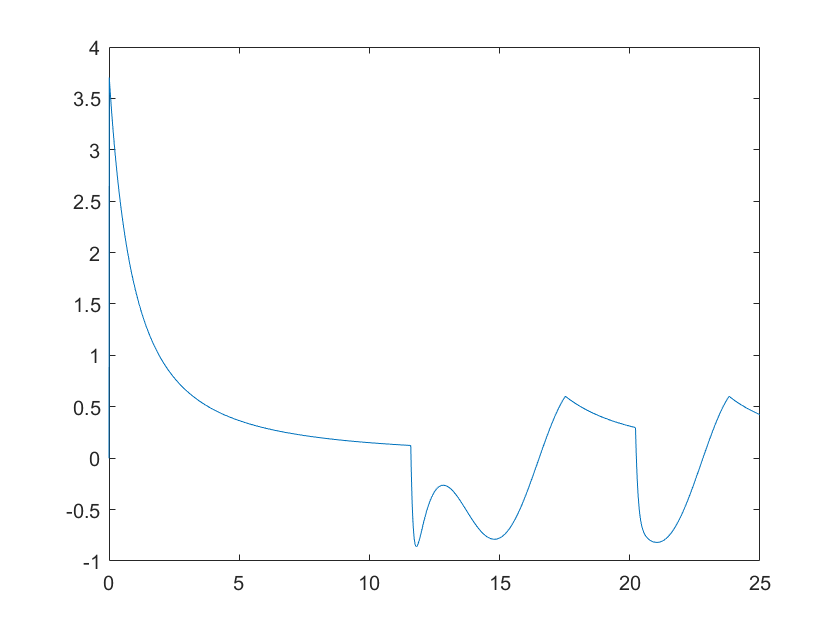

plot(t, F)

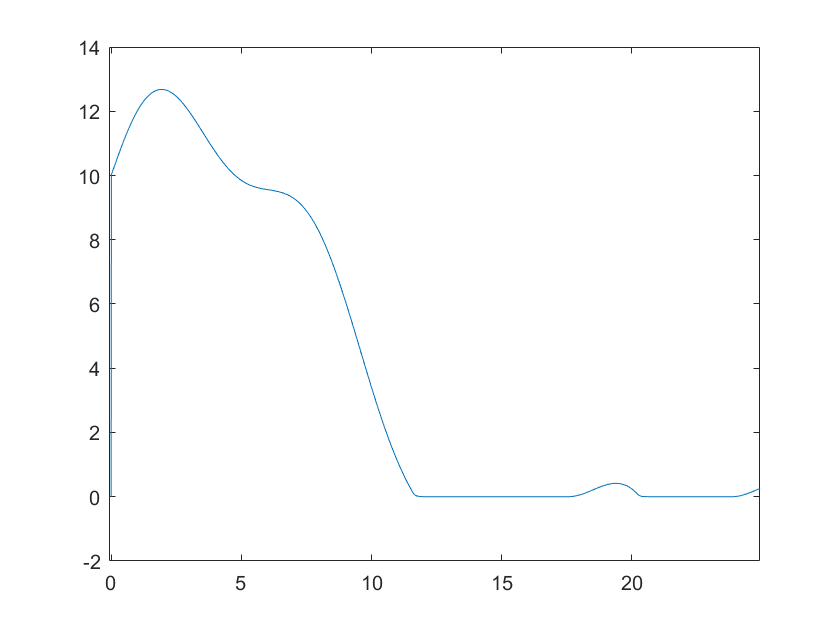

plot(t, B(X))